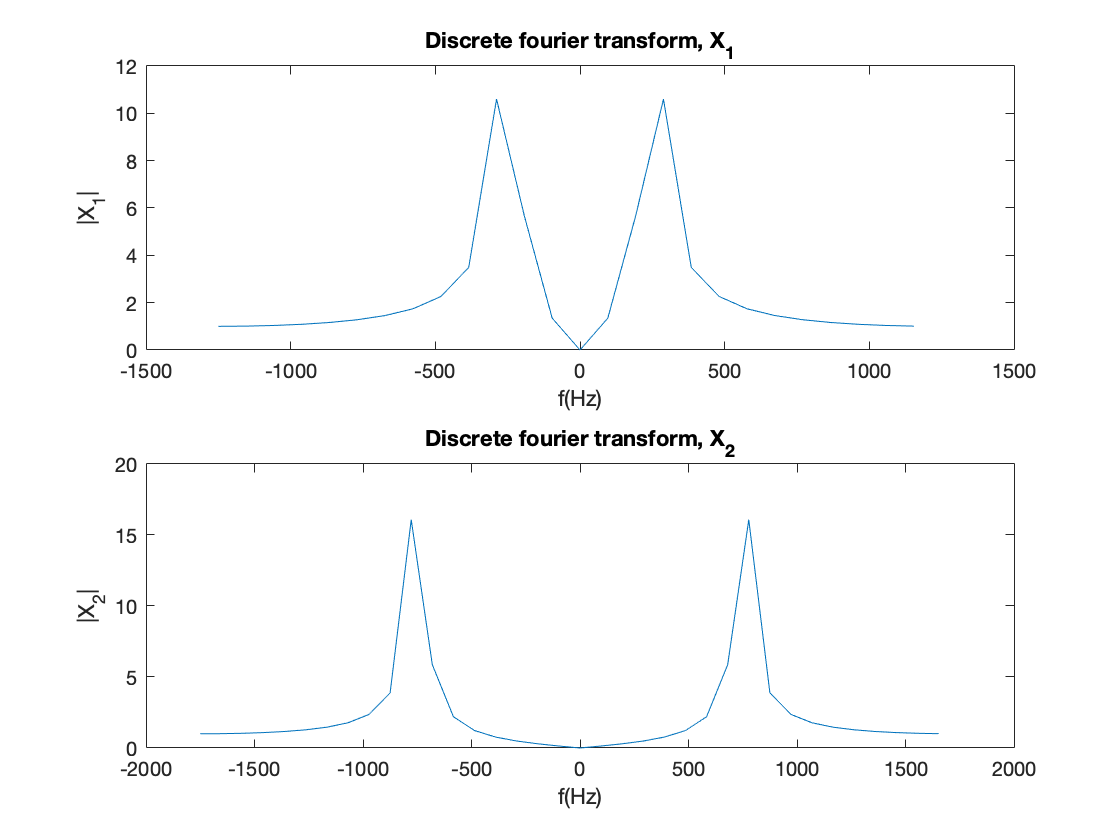

%----------------------------------------------------------------------
%Name : Sumit Patidar
%Roll no: B15237
%Task : Discrete Fourier transform 
%----------------------------------------------------------------------
close all;
clc;

%x_a(t) = cos(2000*pi*t) - it is approximated as discrete 
%by chossing decimated time points
T = 1000;%signal time period
Fs = 10000; %sampling frequency
Ts = 1/Fs; %sampling period
ncycle = 10; %no of cycles to consider
t = 0:T:ncycle/T;
L = length(t);

%given signal
x_a = cos(2000.*pi.*t);

%sampling the signal
Fs1 = 2500;
Ts1 = 1/Fs1;
Fs2 = 3500;
Ts2 = 1/Fs2;

t1 = 0:1/Fs1:ncycle/T;
t2 = 0:1/Fs2:ncycle/T;
L1 = length(t1);
L2 = length(t2);
x1 = cos(2000.*pi.*t1); %sequence 1
x2 = cos(2000.*pi.*t2); %sequence 2
%define size of matrix to hold computed fourier transform values
X1 = zeros(1,L1); 
X2 = zeros(1,L2);

%compute DTFT for signal with Fs = 2500 Hz
%refer to the link for algorithm = https://en.wikipedia.org/wiki/Discrete_Fourier_transform
%the peaks need to be placed at correct frequency locations, which I couldn't figure it out.
for i = 1:L1
    X1(i) = 0;
    for k = 1:L1
        X1(i) = X1(i) + x1(k).*exp(-1j.*2.*pi.*(i-1).*(k-1)./L1);
    end
end

%compute DTFT for signal with Fs = 3500 Hz
for i = 1:L2
    X2(i) = 0;
    for k = 1:L2
        X2(i) = X2(i) + x2(k).*exp(-1j.*2.*pi.*(i-1).*(k-1)./L2);
    end
end

hold on
subplot(2,1,1);
plot(-Fs1/2:Fs1/L1:Fs1/2 - Fs1/L1, abs(X1));
xlabel('f(Hz)');
ylabel('|X_1|');
title('Discrete fourier transform, X_1')

hold on
subplot(2,1,2);
plot(-Fs2/2:Fs2/L2:Fs2/2 - Fs2/L2, abs(X2));
xlabel('f(Hz)');
ylabel('|X_2|');
title('Discrete fourier transform, X_2')